## Identifying a model for the gantry crane

## Generate input data

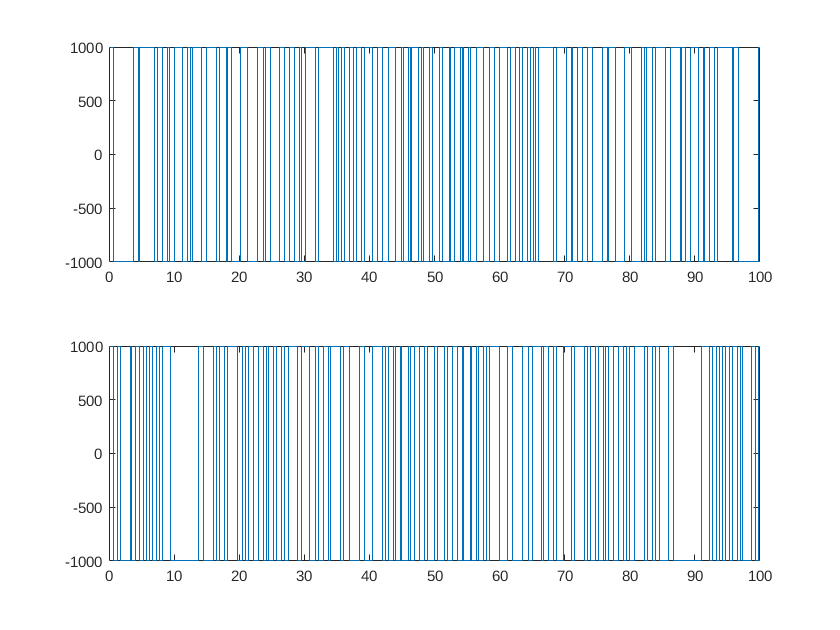


h = 0.25;
N = 400;
Tfinal = N*h;   
uu = idinput(N, 'rbs', [0, 0.5]);
forceMagnitude = 1e3;
u1 = forceMagnitude*uu(1:N/2);
u1v = forceMagnitude*uu(N/2+1:N);
t = (1:N)'*h;
input1 = cat(2, t, cat(1, u1, flipud(u1)));
input1v = cat(2, t, cat(1, u1v, flipud(u1v)));

figure(1)
subplot(211)
stairs(input1(:,1), input1(:,2))
subplot(212)
stairs(input1v(:,1), input1v(:,2))

## Load data

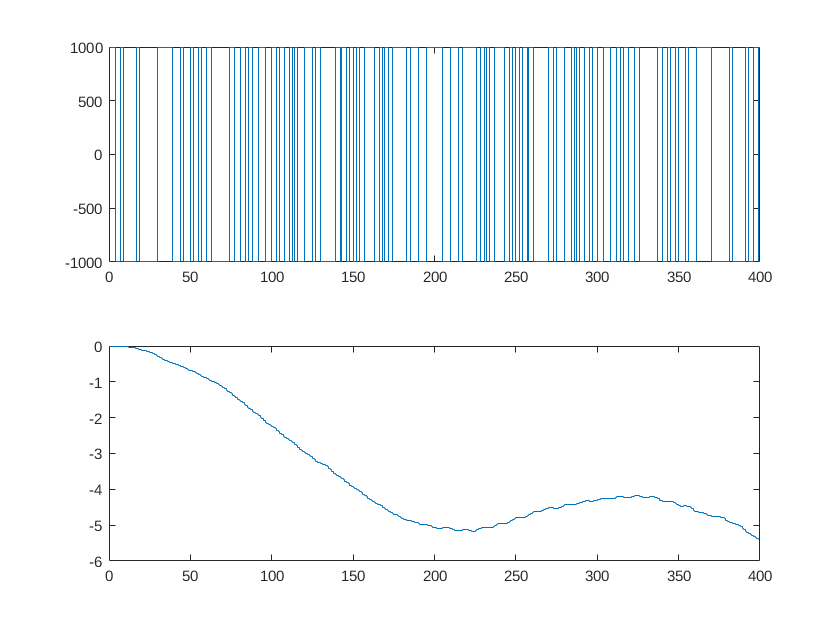

uident = out.simout.Data(3:end,1);
yident = out.simout.Data(3:end,2);

% Prefilter since it is known that the system contains a double integrator
%uident = h^2/2*(uident(2:end) + uident(1:end-1));
%yident = yident(3:end) - 2*yident(2:end-1) + yident(1:end-2);
%uident(end) = [];

figure()
subplot(211);
stairs(uident)
subplot(212)
stairs(yident)

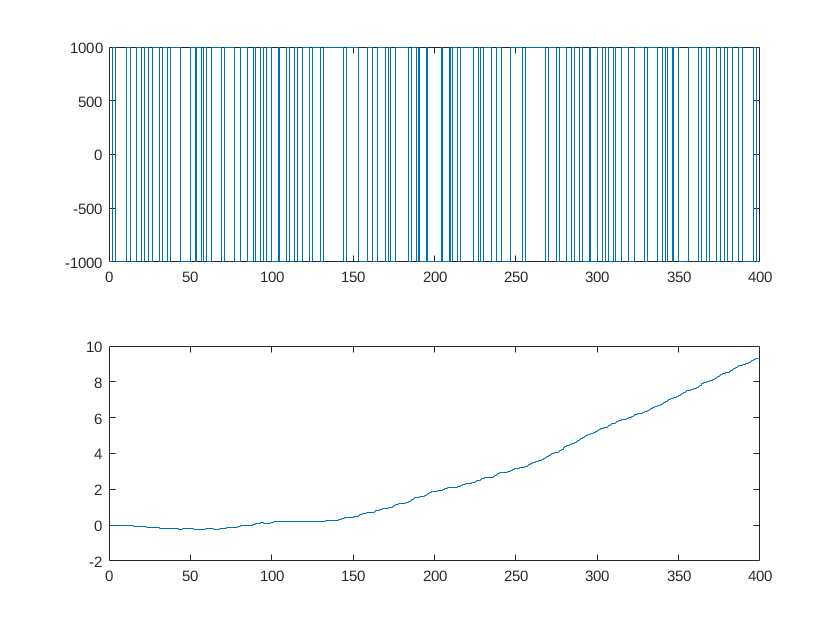



uval = out.simout2.Data(3:end,1);
yval = out.simout2.Data(3:end,2);
%uval = h^2/2*(uval(2:end) + uval(1:end-1));
%yval = yval(3:end) - 2*yval(2:end-1) + yval(1:end-2);
%uval(end) = [];

figure()
subplot(211);
stairs(uval)
subplot(212)
stairs(yval)

## Estimate models

iddta1 = iddata(yident,uident, h);
valdta1 = iddata(yval, uval, h);

% Second order model, one zero, two poles, one delay
% (b0 z + b1) / (z^2 + a1z + a2)
arx221 = arx(iddta1, [2, 2, 1])

arx221 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 1.976 z^-1 + 0.976 z^-2               
                                                   
  B(z) = -4.963e-07 z^-1 + 4.657e-07 z^-2          
                                                   
Sample time: 0.25 seconds
  
Parameterization:
   Polynomial orders:   na=2   nb=2   nk=1
   Number of free coefficients: 4
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 99.7% (prediction focus) 
FPE: 2.571e-05, MSE: 2.495e-05                   



% Second order model, one zero, two poles, two delays
% (b0 z + b1) /(z*(z^2 + a1z + a2))
arx222 = arx(iddta1, [2, 2, 2])

arx222 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 1.975 z^-1 + 0.9745 z^-2              
                                                   
  B(z) = -2.862e-07 z^-2 + 1.16e-06 z^-3           
                                                   
Sample time: 0.25 seconds
  
Parameterization:
   Polynomial orders:   na=2   nb=2   nk=2
   Number of free coefficients: 4
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 99.71% (prediction focus)
FPE: 2.481e-05, MSE: 2.408e-05                   



% fourth order model, three zeros, four poles, one delay
% (b0 z^3 + b1z^2 + b2z + b3) / (z^4 + a1z^3 + a2z^2 + a3z + a4)
arx441 = arx(iddta1, [4, 4, 1])

arx441 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                       
  A(z) = 1 - 3.627 z^-1 + 5.224 z^-2 - 3.564 z^-3 + 0.9681 z^-4           
                                                                          
  B(z) = 1.398e-08 z^-1 + 2.935e-07 z^-2 + 2.586e-07 z^-3 - 9.295e-08 z^-4
                                                                          
Sample time: 0.25 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=4   nk=1
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 99.98% (prediction focus)
FPE: 1.343e-07, MSE: 1.264e-07                   



% sixth order model, five zeros, six poles, one delay
arx661 = arx(iddta1, [6, 6, 1])

arx661 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                        
  A(z) = 1 - 3.233 z^-1 + 4.24 z^-2 - 3.127 z^-3 + 1.911 z^-4 - 1.232 z^-5 + 0.4416 z^-6                   
                                                                                                           
  B(z) = 1.648e-08 z^-1 + 2.852e-07 z^-2 + 3.91e-07 z^-3 + 1.424e-07 z^-4 + 5.674e-08 z^-5 + 7.805e-09 z^-6
                                                                                                           
Sample time: 0.25 seconds
  
Parameterization:
   Polynomial orders:   na=6   nb=6   nk=1
   Number of free coefficients: 12
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 99.98% (prediction focus)
FPE: 9.634e-08, MSE: 8.802e-08                   



% sixth order model, five zeros, six poles, one delay
arx651 = arx(iddta1, [6, 5, 1])

arx651 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                        
  A(z) = 1 - 3.233 z^-1 + 4.241 z^-2 - 3.139 z^-3 + 1.931 z^-4 - 1.247 z^-5 + 0.4457 z^-6  
                                                                                           
  B(z) = 1.673e-08 z^-1 + 2.856e-07 z^-2 + 3.911e-07 z^-3 + 1.417e-07 z^-4 + 6.172e-08 z^-5
                                                                                           
Sample time: 0.25 seconds
  
Parameterization:
   Polynomial orders:   na=6   nb=5   nk=1
   Number of free coefficients: 11
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 99.98% (prediction focus)
FPE: 9.59e-08, MSE: 8.806e-08                    



% sixth order model, five zeros, six poles, two delays
arx662 = arx(iddta1, [6, 6, 2])

arx662 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                         
  A(z) = 1 - 3.217 z^-1 + 4.188 z^-2 - 3.065 z^-3 + 1.883 z^-4 - 1.237 z^-5 + 0.4473 z^-6                   
                                                                                                            
  B(z) = 2.937e-07 z^-2 + 3.885e-07 z^-3 + 1.493e-07 z^-4 + 7.087e-08 z^-5 - 1.796e-08 z^-6 + 4.795e-08 z^-7
                                                                                                            
Sample time: 0.25 seconds
  
Parameterization:
   Polynomial orders:   na=6   nb=6   nk=2
   Number of free coefficients: 12
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 99.98% (prediction focus)
FPE: 9.49e-08, MSE: 8.671e-08                    



% eigth order model, seven zeros, eight poles, one delay
arx881 = arx(iddta1, [8, 8, 1])

arx881 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                                                           
  A(z) = 1 - 3.085 z^-1 + 3.905 z^-2 - 2.819 z^-3 + 1.646 z^-4 - 1.062 z^-5 + 0.6265 z^-6 - 0.3901 z^-7 + 0.1783 z^-8                         
                                                                                                                                              
  B(z) = 1.532e-08 z^-1 + 2.915e-07 z^-2 + 4.275e-07 z^-3 + 2.419e-07 z^-4 + 1.945e-07 z^-5 + 9.932e-08 z^-6 + 3.644e-08 z^-7 + 5.435e-08 z^-8
                                                                                                                                              
Sample time: 0.25 seconds
  
Parameterization:
   Polynomial orders:   na=8   nb=8   nk=1
   Number of free coefficients: 16
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX o


% 12th order model, 
arx12121 = arx(iddta1, [12, 12, 2])

arx12121 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                                                                         
                                                                                                                                                            
  A(z) = 1 - 2.992 z^-1 + 3.637 z^-2 - 2.531 z^-3 + 1.42 z^-4 - 0.8855 z^-5 + 0.5172 z^-6 - 0.279 z^-7 + 0.1552 z^-8 - 0.1187 z^-9 - 0.05117 z^-10          
                                                                                                                             + 0.284 z^-11 - 0.1569 z^-12   
                                                                                                                                                            
                                                                                                                                                            
  B(z) = 3.001e-07 z^-2 + 4.558e-07 z^-3 + 2.82


% Fourth order state space model
%ss4 = n4sid(iddta1, 4);

% Sixth order state space model
%ss6 = n4sid(iddta1, 6);


## Compare models

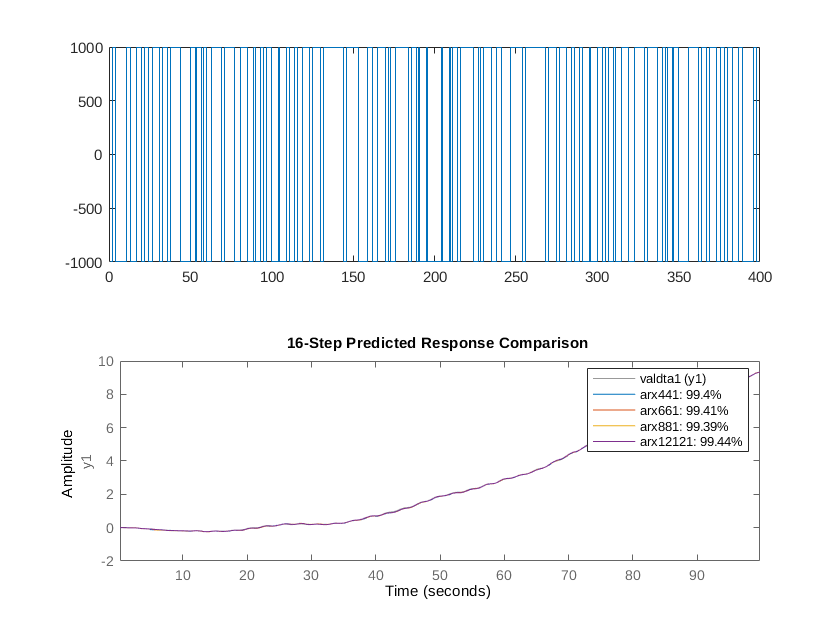

compare(valdta1, arx441, arx661, arx881, arx12121, 16)

aic(arx441, arx661, arx881, arx12121)

Model quality according to the "nAIC" measure:
  -15.8234  -16.1554  -16.2423  -16.3286



## Export models for use in Simulink

[num, den] = tfdata(tf(arx441))

num = 1×1 cell array
    {[0 1.3975e-08 2.9354e-07 2.5865e-07 -9.2952e-08]}


den = 1×1 cell array
    {[1 -3.6273 5.2236 -3.5644 0.9681]}


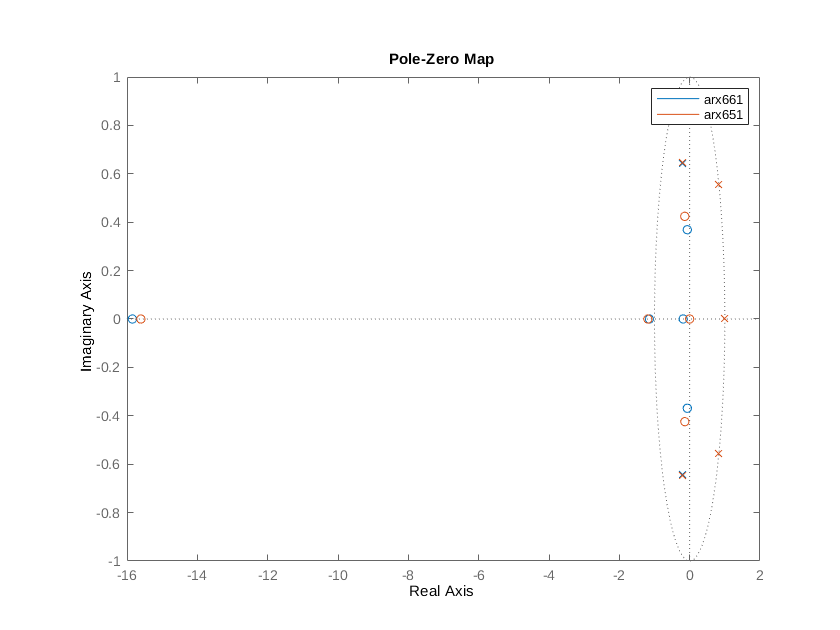

figure()
clf
pzmap(arx661, arx651)
legend

save crane_sysid_result.mat arx441 arx661
save crane_sysid_result_2022.mat arx661 h iddta1
